**Image Processing and Signal Processing TD1**

**Student Name: **

**Abdelaziz Aissa**

**MOUHOUBI MAHFOUD**

**Exercise 01 : ****Interpretation of frequency content**

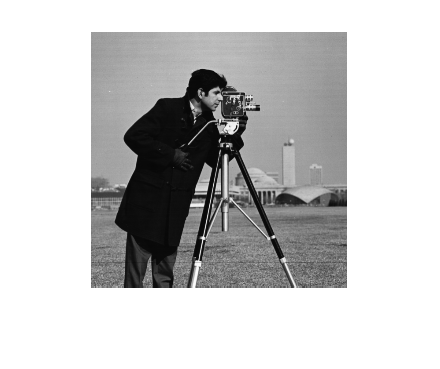

img1=imread('cameraman.tif');
img1=imresize(img1,[256,256]);
imshow((img1))

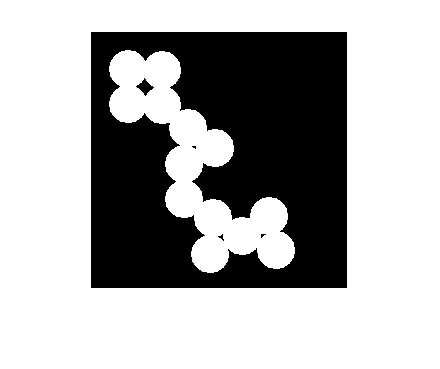

img2=imread('circles.png');
%img2=rgb2gray(img2);
img2=imresize(img2,[256,256]);
imshow((img2))

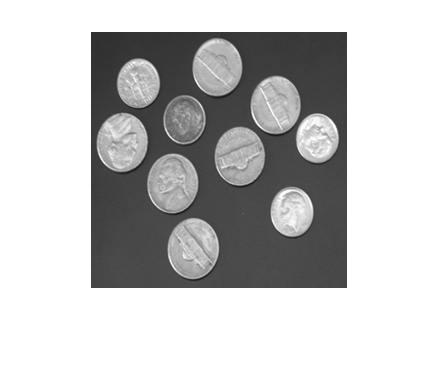

img3=imread('coins.png');
%img3=rgb2gray(img3);
img3=imresize(img3,[256,256]);
imshow((img3))

1- Calculate the centered Fourier transform of an image of your choice in grayscale. Display the module or the real part of this transform either in an image or in a graphic (surf function, image, imagesc, imshow, etc.).

 **We will use: log(1 + abs(fft2(I))**

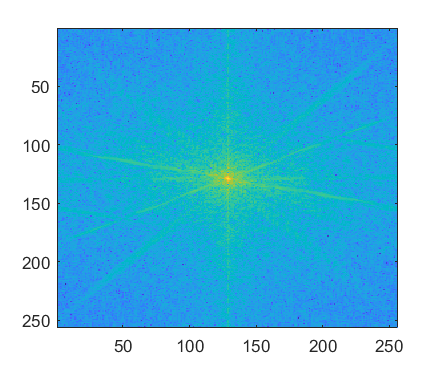

fftImage =fftshift( fft2(img1)); %calculating the fourier transform and do the shift to display the low frequancy in the middle  
fftImageNorm = log(1+abs(fftImage)); %Normalize the Fourier transform of our image 
imagesc(fftImageNorm) ;

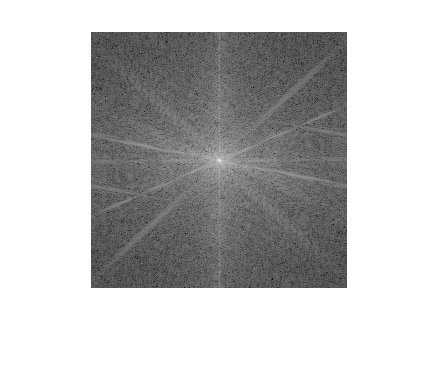

imshow((fftImageNorm),[]) % Plot the Fourier transform 

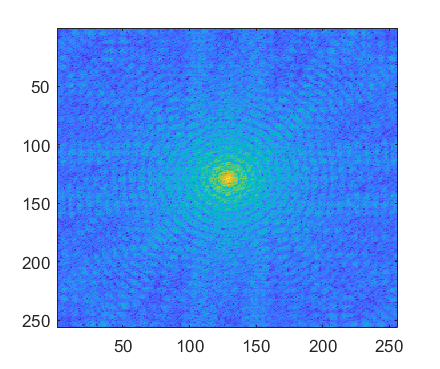

%we repeat the same step for other images 
%Image 2
fftImage2 =fftshift( fft2(img2)); %Transform the image into RGB using "rgb2gray"
fftImageNorm2 = log(1+abs(fftImage2)); 
imagesc(fftImageNorm2);

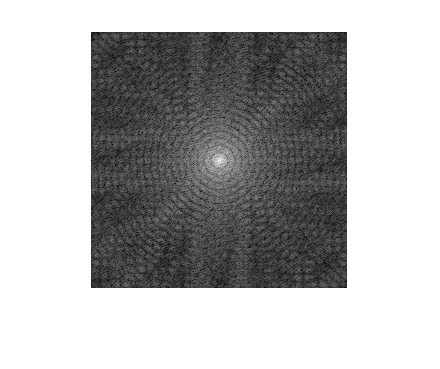

imshow((fftImageNorm2),[])

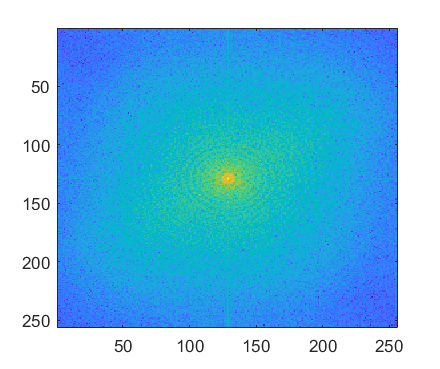

%Image 3
fftImage3 =fftshift( fft2(img3)); %Transform the image into RGB using "rgb2gray"
fftImageNorm3 = log(1+abs(fftImage3)); 
imagesc(fftImageNorm3);

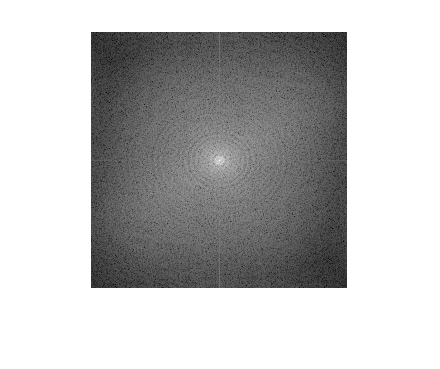

imshow((fftImageNorm3),[])

**2. Where are the low frequencies and the high frequencies ?**

**Answer:**

- **The low frequencies are located in the middle of our image(Center) with high amplitude  (white images )**

- **The high frequencies are located in the border of our image with low frequencies (Black images )**

**The coefficients having the greatest amplitude?**

**Answer:**

- **the coefficients having the high frequency are located at the center of the image which represent the white color  **

**Test on several images. Comment according to the frequency content of the images:**

**Image  : **

**We can notice that not all the low fequencies have a high amplitude .However ,most of the low frequencies at the border of the image have low amplitude (Black Color). **

**Image 3 : **

**we can notice that most the low fequencies have a high amplitude.However ,we can see that also the high frequencies on the horizontal and the vertical access have also high amplitude (white color). **

**3- Find the average of the gray levels of the image using the Fourier transform : **

avg=sum(fftImageNorm(:))/(256*256) ; 
disp(avg)

    7.8363



**Exercise 2 : Properties of the Fourier transform**

**1. Linearity:**

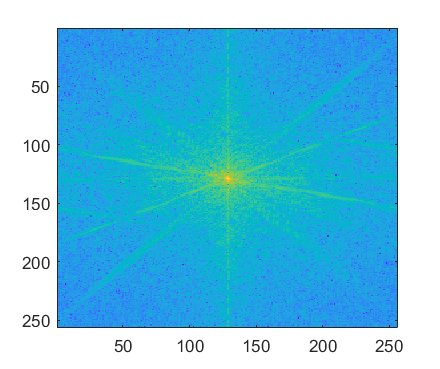

%Ploting fourier transform of F(a)+F(b)
fftImage_ab = fftshift(fft2(img1)+ fft2(img2));
fftImageNorm4 = log(1+abs(fftImage_ab)); 
imagesc(fftImageNorm4);

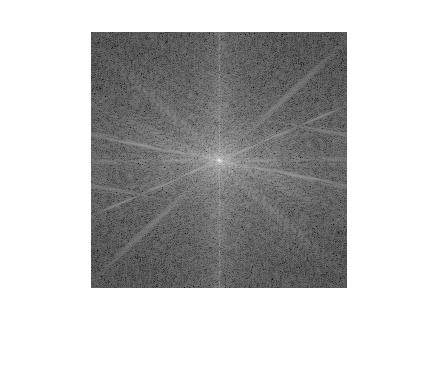

imshow((fftImageNorm4),[])

%Ploting fourier transform of F(a+b) 
fftImagea_b =fftshift(fft2(double(img1)+double(img2)));
fftImageNorm5 = log(1+abs(fftImagea_b)); 
imshow((fftImageNorm5),[])

%Display the diffrence between the F(a)+F(b) and F(a+b)
diff=max(fftImageNorm4-fftImageNorm5);

The property of linearity is verified 

**2. Rotation:**

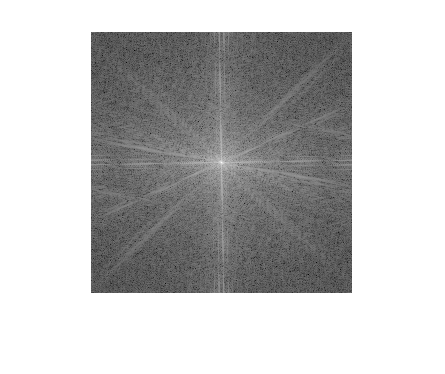

%we use imrotate to rotate the image
B = imrotate(img1,1);
fftImage_rotb = fftshift(fft2(B));
fftImageNormb = log(1+abs(fftImage_rotb)); 
imshow((fftImageNormb),[])

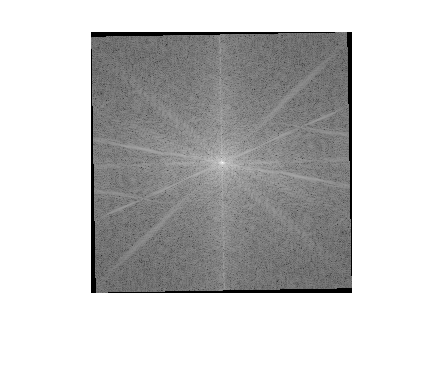

%We rotate the fourier transform of the image
fft_rotate = imrotate(fftImageNorm,1);
imshow((fft_rotate),[])

We can see that the two images are similar

- The property of Rotation is verified 

**3. What is the result of the Fourier transform of I(x,y) × (−1)x+y ? **

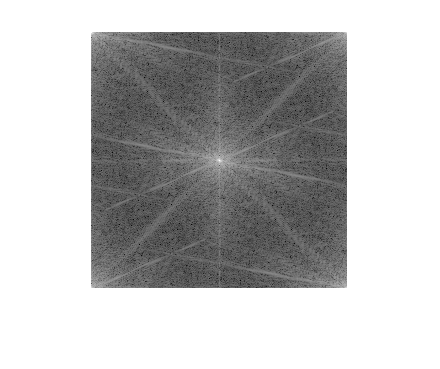

[ny,nx] = size(img1);
I=zeros(nx,ny);
for x=1:nx
    for y=1:ny
        I(x,y)=img1(x,y)*(-1)^(x+y);%Save the values 
    end
end
fftimg_I=fft2(I);
fftimg_I=log(1+abs(fftimg_I));
imshow(fftimg_I,[])

% Display the image with fftshift 
fftimg=fft2(img1);
fftimg=log(1+abs(fftimg));
imshow(fftshift(fftimg),[])

**What property of the Fourier transform is revealed?**

**We remark that the fourier transform is shifted to the center of the image without using fftshift **

- **this  methods is used fot translation to the center of the image **

Exercise 3 : Fourier transform of basic images 

Calculate the 2D DFT of the following images:

1. A sinusoid function :

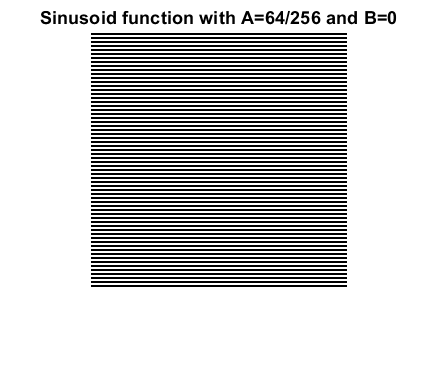

[ny,nx] = size(img1);
A=64/256;
B=0;
I2=zeros(nx,ny);
for x=1:nx
    for y=1:ny
        I2(x,y)=255*(sin(2*pi*(A*x+B*y)+1)/2);
    end
end
imshow(I2);
title('Sinusoid function with A=64/256 and B=0')

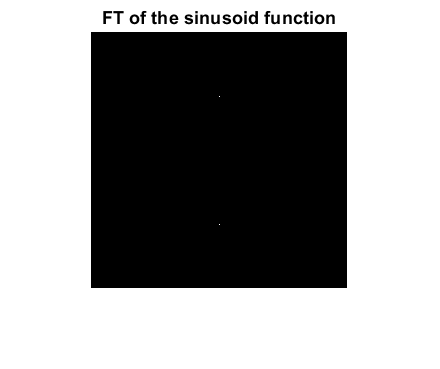

fftImage_I2 = fftshift(fft2(I2));
fftImageNormI2 = log(1+abs(fftImage_I2)); 
imshow(fftImageNormI2)
title('FT of the sinusoid function')

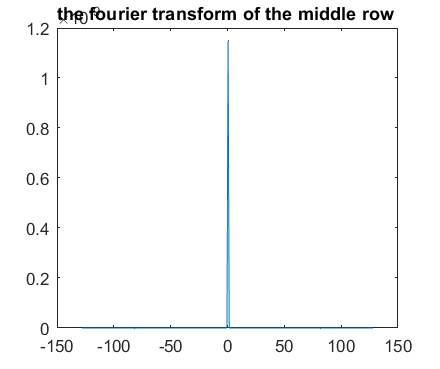

%PLoting the row 128 (middle of the image)
x=linspace(-128,128,256);
plot(x,fftImageNormI2(128,:))
title('the fourier transform of the middle row ')

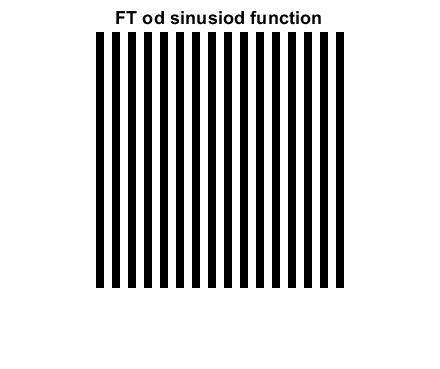

%Test it on several values of A and B
A=1;
B=16/256;
I3=zeros(nx,ny);
for x=1:nx
    for y=1:ny
        I3(x,y)=255*(sin(2*pi*(A*x+B*y)+1)/2);
    end
end
imshow(I3)
title('Sinusoid function with A=1 and B=16/255')
fftImage_I3 = fftshift(fft2(I3));
fftImageNormI3 = log(1+abs(fftImage_I3)); 
title('FT od sinusiod function')

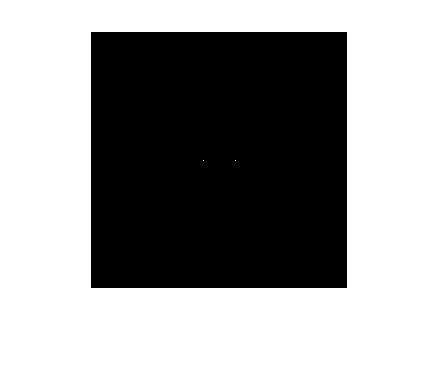

imshow(fftImageNormI3)

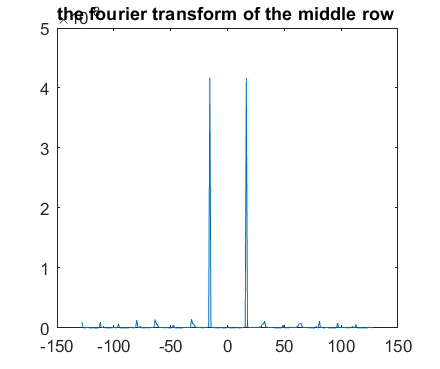

x=linspace(-128,128,256);
plot(x,fftImageNormI3(128,:))
title('the fourier transform of the middle row ')

**2. A gate function (image of a rectangle):**

**We remark that we are getting product of 2 Sinc functions as we saw in the lecture and it attenuate the high frequncies **

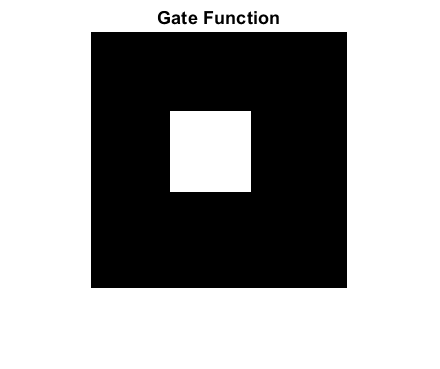

G = zeros(256,256);
G(80:160, 80:160) = 1;
imshow(G,[])
title('Gate Function')

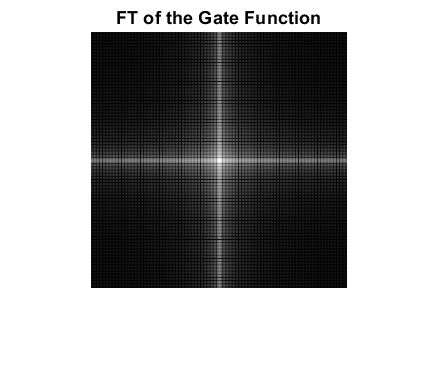

fft_G = log(1 + abs(fftshift(fft2(G))));
imshow(fft_G,[])
title('FT of the Gate Function')

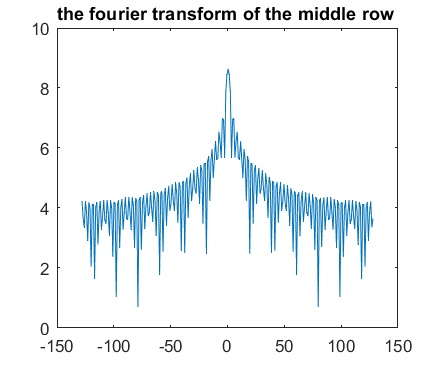

%PLoting the row 128 (middle of the image)
x=linspace(-128,128,256);
plot(x,fft_G(128,:))
title('the fourier transform of the middle row ')

**3. A Gaussian (use fspecial):**

**Gaussian filter is low pass filter used for reducing noise**

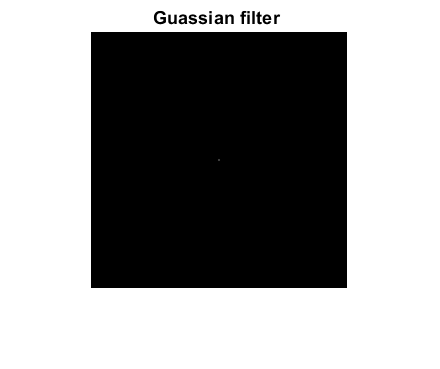

H = fspecial('gaussian',[256,256]);
imshow(H)
title('Guassian filter ')

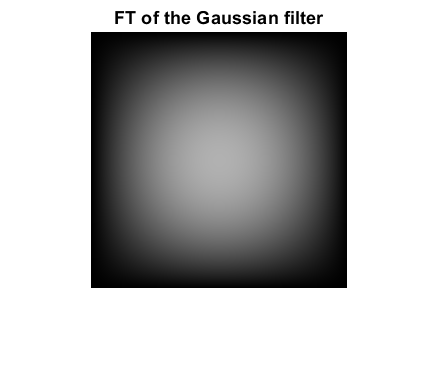

fftImage_H = fftshift(fft2(double(H)));
fftImageNormH = log(1+abs(fftImage_H)); 
imshow(fftImageNormH)
title('FT of the Gaussian filter')

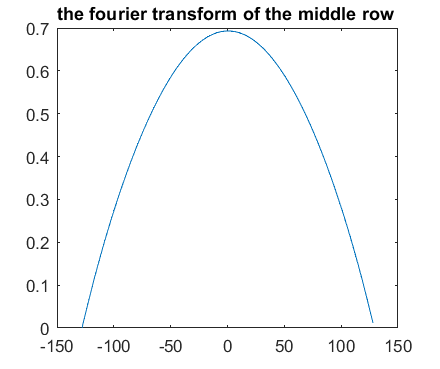

%PLoting the row 128 (middle of the image)
x=linspace(-128,128,256);
plot(x,fftImageNormH(128,:))
title('the fourier transform of the middle row ')

**4. A Uniform average filter (use fspecial):**

**It's a low pass filter and the porpose of using it is to smooth or blur the image.  **

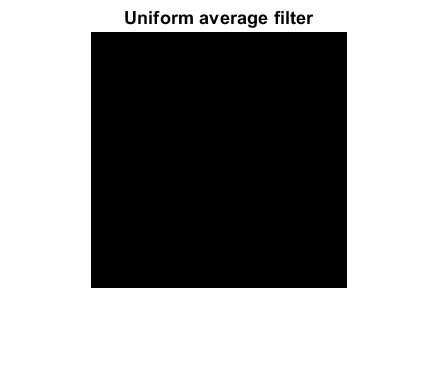

U = fspecial('average',[256,256]);
imshow(U)
title('Uniform average filter')

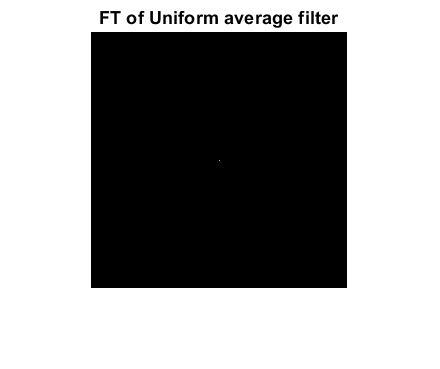

fftImage_U = fftshift(fft2(double(U)));
fftImageNormU = log(1+abs(fftImage_U)); 
imshow(fftImageNormU)
title('FT of Uniform average filter')

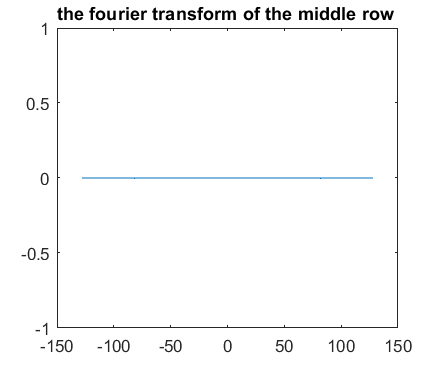

%PLoting the row 128 (middle of the image)
x=linspace(-128,128,256);
plot(x,fftImageNormU(128,:))
title('the fourier transform of the middle row ')

**5. A Laplacian filter:**

**Laplacian filter is a high pass filter used for edge detection . **

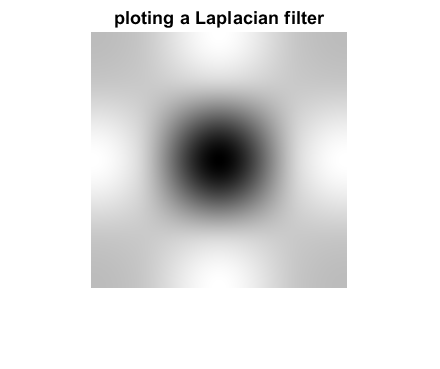

L1 = fspecial('laplacian',0.2);
L=imresize(L1,[256 256]);
imshow(L,[])
title('ploting a Laplacian filter')

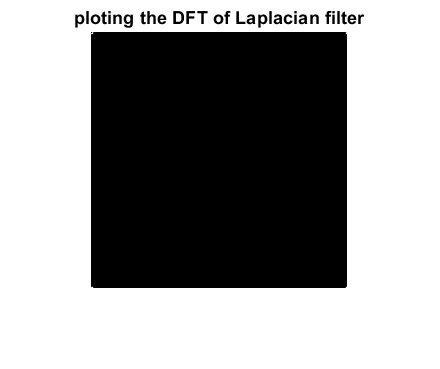

fftImage_L = fftshift(fft2(double(L)));
fftImageNormL = log(1+abs(fftImage_L));
imshow(abs(fft2(L)),[])
title('ploting the DFT of Laplacian filter')

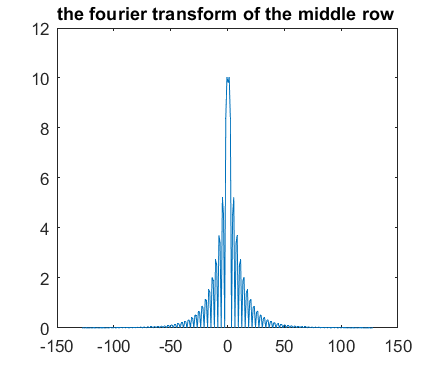

%PLoting the row 128 (middle of the image)
x=linspace(-128,128,256);
plot(x,fftImageNormL(128,:))
title('the fourier transform of the middle row ')

**Exercise 4 : Fourier transform and convolution**

**we will show that a convolution in the spatial domain is equivalent to a multiplication in the frequency domain:**

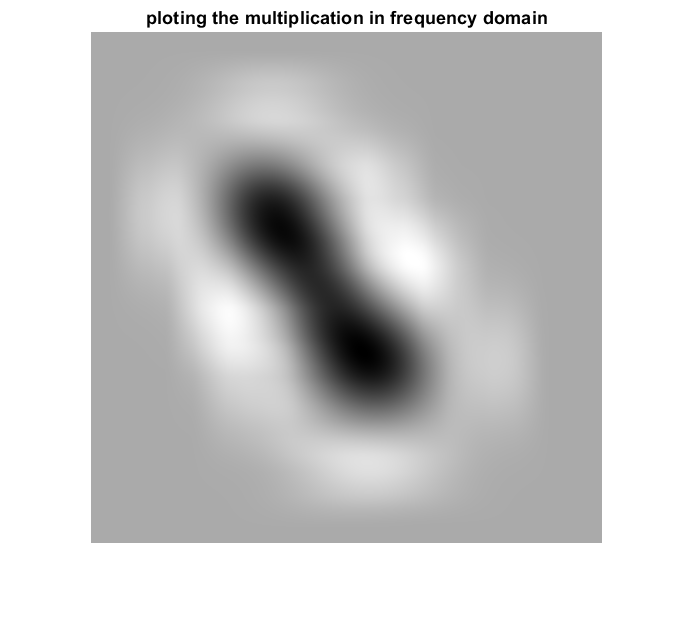

cnv=conv2(img2,L);%Convolve our image with laplacian filter
imshow(cnv,[]) % display the result
title('ploting the image convolved with the Laplacian filter')
fft_image=fft2(double(img2)) ; %calculate the fourier transform of our image 
fft_L=fft2(double(L)); %calculate the fourier transform of the Laplacian filter 
mlt=ifft2(fft_image .* fft_L) ; %Perform the multiplication 
title('ploting the multiplication in frequency domain')

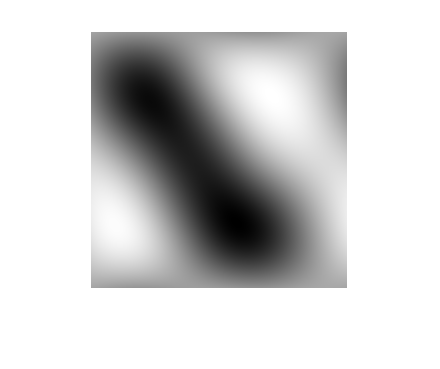

imshow(fftshift(mlt),[]) % Display the result obtained 

- **We can confirm that the convolution in frequency domain is multiplication in time domain** 

**Exercise 5 : Sampling**

**1- Calculate the Fourier transform of a pulse train :**

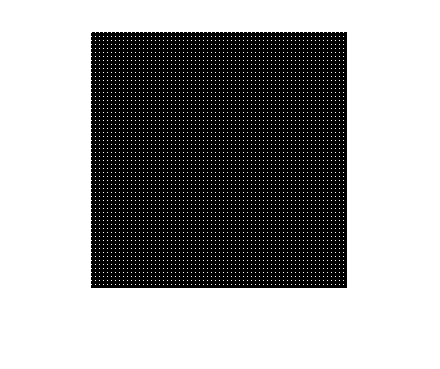

A=zeros(4,4); %generate a 4 by 4 array 
A(1,1)=1; % set the centered pixel to 1 and the other pixels to zero 
B=repmat(A,int8(256/4),int8(256/4)); 
B2=imresize(B,[256 256]); %we make sure that our image is 256 by 256
imshow(B,[]) %plot the pulse train

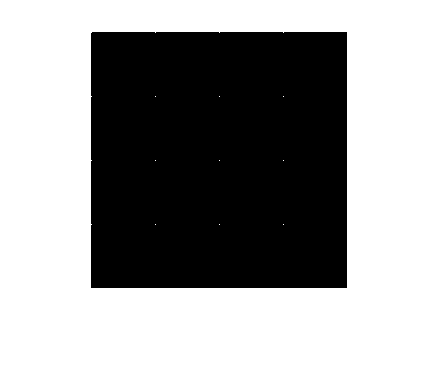

fft_B=fft2(double(B2));%calculate the fourier transform of the pulse train
imshow(abs(fft_B),[])

**2- Sample the image of Camerman and  then the UCSB image using the generated pulse train : **

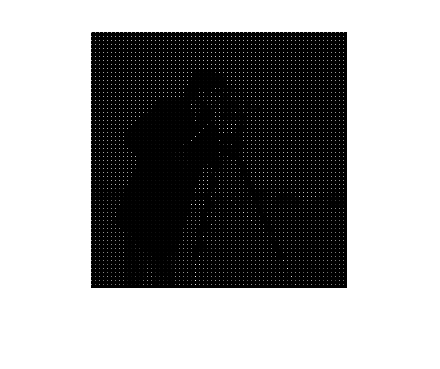

%Sample the image of the Cameraman using pulse train :
mlt_s=double(img1) .* double(B2) ;
imshow(mlt_s,[]) 

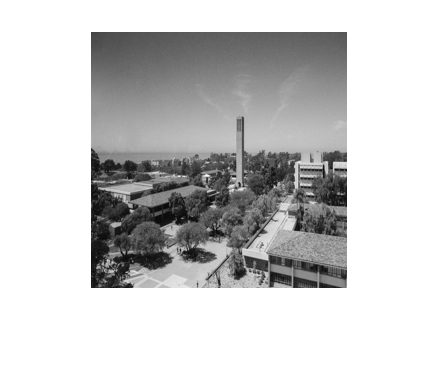

%Upload the USCB Image :
USCB=rgb2gray(imresize(imread('C:\Users\Aissa\OneDrive\Desktop\TD1\ucsb-stork-tower.jpg'),[256 256]));
imshow(USCB)

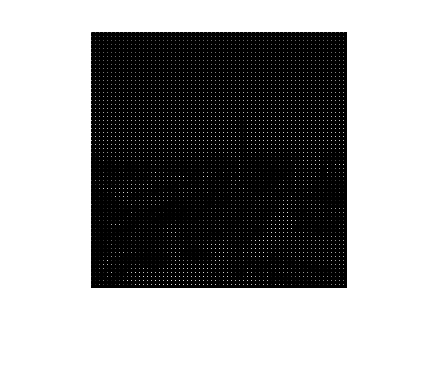

%Sample the image of USCB :
mlt_uscb=double(USCB) .* double(B2) ;
imshow(mlt_uscb,[])

**3. Calculate the 2D DFT of the sampled image. and make the link with the theoretical results seen in class:**

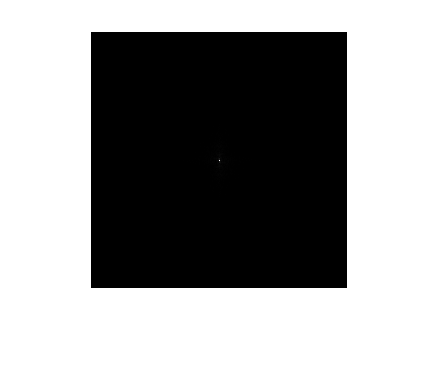

%Calculating the fourier transform of the original image
fft_uscb=fft2(USCB);
imshow(fftshift(abs(fft_uscb)),[])

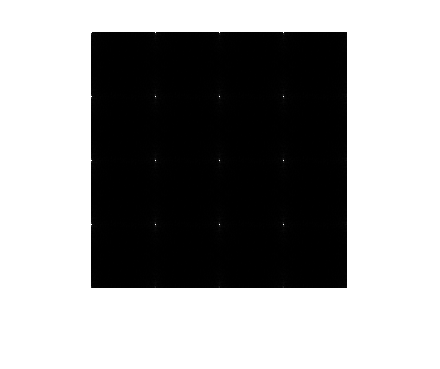

%Calculating the fourier transform of the sampled image
fft_sampledimg=fft2(mlt_uscb);
imshow(abs(fft_sampledimg),[])

**Answer :** 

**We can notice that the fourier transfom of the sampled image is a replication of the fourier transform of the original one around the sampling frequency which is the property of the sampling technique we saw in the lecture . **

**4. Suggest a way to find the original image from the sampled image knowing that the sampling highlights the phenomena of Aliasing : **

**Answer :**

**We can sample the original image with sampling frequency greater than 2*Fmax and after that we can use a low pass filter e.g: Gaussian Filter / Butterworth filter , with a bandwidth of 2*Fmax ,respecting all these condition we will be able to reconstruct the original signal perfectly ,Howerver , If the sampling frequency is less than 2*Fmax we will face the problem of aliasing in which will not be able distinguish and reconstruct our original signal .**

**Exercise 6 : Filtering in the frequency domain**

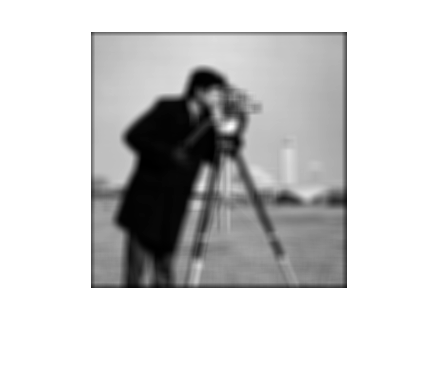

%Low pass filter
U = fspecial('average',[10,10]);
I1 = imfilter(img1,U);
imshow(I1,[])

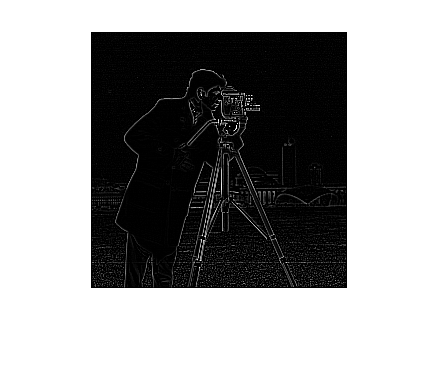

%High pass filter with laplacian
H2 = fspecial('laplacian',0.5);
I2 = imfilter(img1,H2);
imshow(I2,[])

%High pass filter with soble
I3 = edge(img1,'sobel');
imshow(I2,[])

- **We can conclude from the results that the low pass filter is used to reduce the noise and Smooth the output image and the high pass filter is used for edge detection .we obtaibed this result because the noises are considered as high frequency samples **

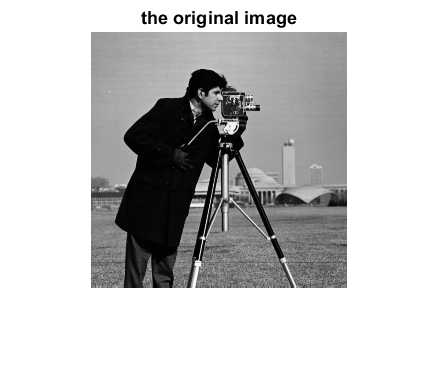

%Compare ideal filters with Butterworth filters : 
%Ideal filter 
[M, N] = size(img1);
FT_img=fft2(double(img1));
% Assign Cut-off Frequency  
D0 = 25;
% Designing filter
u = 0:(M-1);
idx = find(u>M/2);
u(idx) = u(idx)-M;
v = 0:(N-1);
idy = find(v>N/2);
v(idy) = v(idy)-N;
% of v, and matrix U with each column is a copy of u
[V, U] = meshgrid(v, u);
% Calculating Euclidean Distance
D = sqrt(U.^2+V.^2);
%the order of the filter
n=5 ;
% determining the filtering mask
H_Lowpass = double(D <= D0);
B_Butterworth=double(1+(D./D0)^2*n);
% image and the mask
G = H_Lowpass.*FT_img;
% ifft2 (2D inverse fast fourier transform)  
output_image = real(ifft2(double(G)));
% Displaying Input Image and Output Image
imshow(img1,[])
title ("the original image")

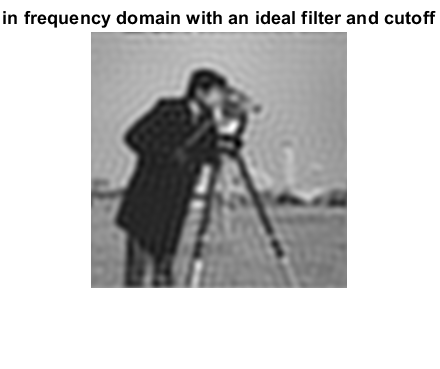

imshow(output_image,[])
title ("filtering the image in frequency domain with an ideal filter and cutoff frequancy of 25Hz")

G_butterworth = B_Butterworth.*FT_img;
% ifft2 (2D inverse fast fourier transform)  
output_image_butter = real(ifft2(double(G_butterworth)));
% Displaying Input Image and Output Image
imshow(img1,[])
title ("the original image")

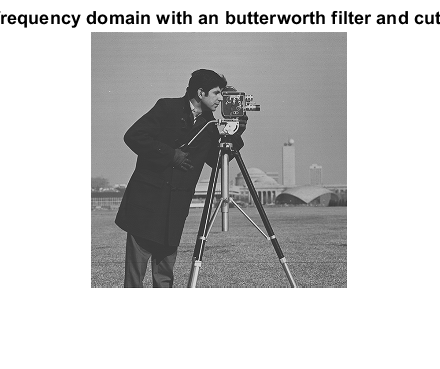

imshow(output_image_butter,[])
title ("filtering the image in frequency domain with an butterworth filter and cutoff frequancy of 25Hz")

- **Vary the cutoff frequencies: **

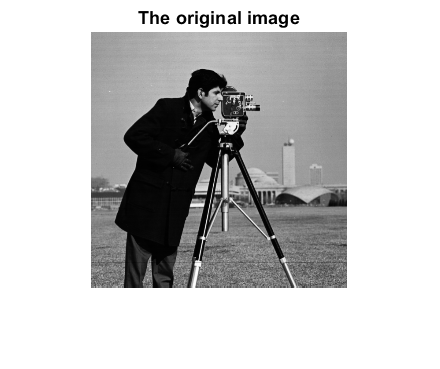

D0 = 50;
% Designing filter
u = 0:(M-1);
idx = find(u>M/2);
u(idx) = u(idx)-M;
v = 0:(N-1);
idy = find(v>N/2);
v(idy) = v(idy)-N;
% of v, and matrix U with each column is a copy of u
[V, U] = meshgrid(v, u);
% Calculating Euclidean Distance
D = sqrt(U.^2+V.^2);
%the order of the filter
n=5;
% determining the filtering mask
H_Lowpass = double(D <= D0);
B_Butterworth2=double(1+(D./D0)^2*n);
% image and the mask
G2 = H_Lowpass.*FT_img;
% ifft2 (2D inverse fast fourier transform)  
output_image2 = real(ifft2(double(G2)));
% Displaying Input Image and Output Image
imshow(img1,[])
title ("The original image")

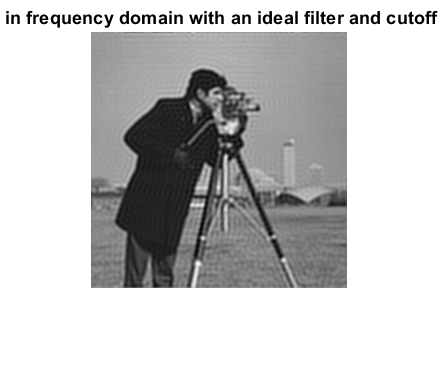

imshow(output_image2,[])
title ("Filtering the image in frequency domain with an ideal filter and cutoff frequancy of 50Hz")

G_butterworth2 = B_Butterworth2.*FT_img;
% ifft2 (2D inverse fast fourier transform)  
output_image_butter2 = real(ifft2(double(G_butterworth2)));
% Displaying Input Image and Output Image
imshow(img1,[])
title ("The original image")

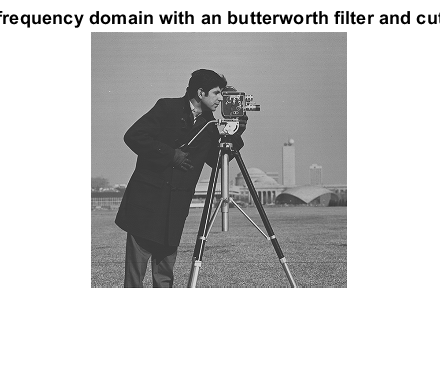

imshow(output_image_butter2,[])
title ("Filtering the image in frequency domain with an butterworth filter and cutoff frequancy of 50Hz")

**Comparaison : Ideal filter has sharp cutoff fequency which result a blurring image (the noise is strictly reduced ) ,However ,thr Butterworth filter has more gradual transition between the passband and stopband(it depends on the order of the filter) which cause less distortion and more smoothness .**